disp('linear regression power model');

linear regression power model


% power model
% y = bx^a
x = [1 2 3 4 5] ; 
y = [0.5 1.7 3.4 5.7 8.4];

%log y= a log x + log b 
% Y = a X + B 
%take the log for the x,y vectors 
X = log10(x);
Y = log10(y);

% ∑ Y = a ∑ X + n B
% ∑ YX = a ∑ X^2 + B ∑ X

% get variable values

n=length(x)     ;  % n  
sX = sum(X)     ; % ∑ X
sY = sum(Y)     ; % ∑ Y
sXY = sum(X.*Y) ; % ∑ YX
sX2 = sum(X.^2) ; % ∑ X^2

% ∑ Y = a ∑ X + n B
% ∑ YX = a ∑ X^2 + B ∑ X

% we split this two equation into two matrices

Rightcoef = [sX n  ; sX2 sX ] ;  
Leftcoef = [sY ; sXY] ; 
%solve as matrices
%think of it as 
%Leftcoef = Rightcoef  * sol
sol = Rightcoef \ Leftcoef ;  % as same as 'sol  = Rightcoef^-1 * Leftcoef' but the backslash expression is more effcint for more info : https://www.mathworks.com/help/matlab/ref/mldivide.html

a = sol(1) ;   %a
B = sol(2) ;   %B
b= 10^B ;      %b 

%calc R^2
yav = mean(Y) ;
st = sum( (Y-yav).^2 )  ;
sr = sum((Y-B-a*X).^2) ;
r2=(st-sr)/st ;


disp('a ');disp(a) ;

a 
    1.7517



disp('b ');disp(b) ;

b 
    0.5009



disp('r^2 ');disp(r2) ;

r^2 
    1.0000



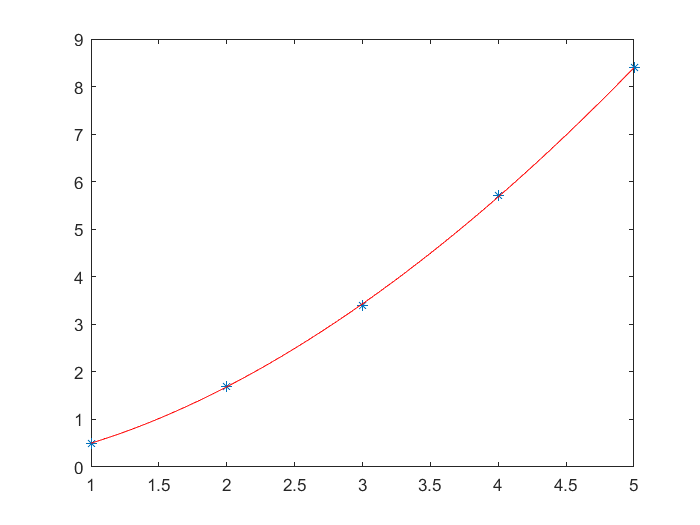


x1 = min(x):0.1:max(x) ;
%y=b*x^a
y1 = b*x1.^(a);

plot(x,y ,'*' , x1 ,y1 ,'r-')